### Demo

clear
sizes = [144,7,52,10];
load nyc_tensors.mat
load regions.mat
arrs = squeeze(sum(reshape(arrs,6,24,365,[]),1));
Y = double(reshape(arrs(:,1:364,regions), 24, 7, 52,[]));
Y(:,1,53,:) = arrs(:,365,regions);
Y(:,2:7,53,:) = mean(Y(:,2:7,1:52,:),3);

sizes = [24,7,53,81];
number_anomaly = 1000;
length_anomaly = 8;
amplitude_anomaly = 50;
[M, Y_gen, Yn, ind_removed, mat_anom] =gendata(sizes, number_anomaly, length_anomaly, amplitude_anomaly, Y);
m= t2m(M,4);
y= t2m(Y_gen,4);
z= t2m(Yn,4);

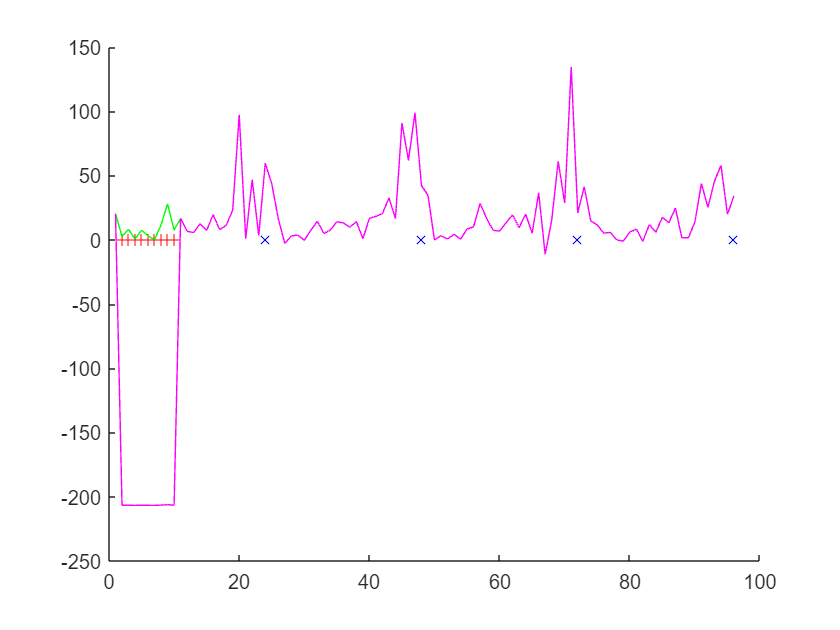

t= [1:200];
figure;
scatter(t(mod(1:96,24)==0),0,'bx')
hold on;

scatter(t(m(28,1:96)==1),0,'r+')
hold on
plot(y(28,1:96),'g')
plot(z(28,1:96),'m')

param = set_params(Yn);
% param.beta_1=0.1;
% param.beta_2=0.1;
% param.beta_3=0.1;
% param.lambda=1/81;
% param.gamma=1/81;
% param.psi=1;
% param.alpha=0;
% param.err_tol=1e-5;
param.max_iter=200;
param.ind_m =ind_removed;
[L,S,~]= loss(Yn, param);

Converged!


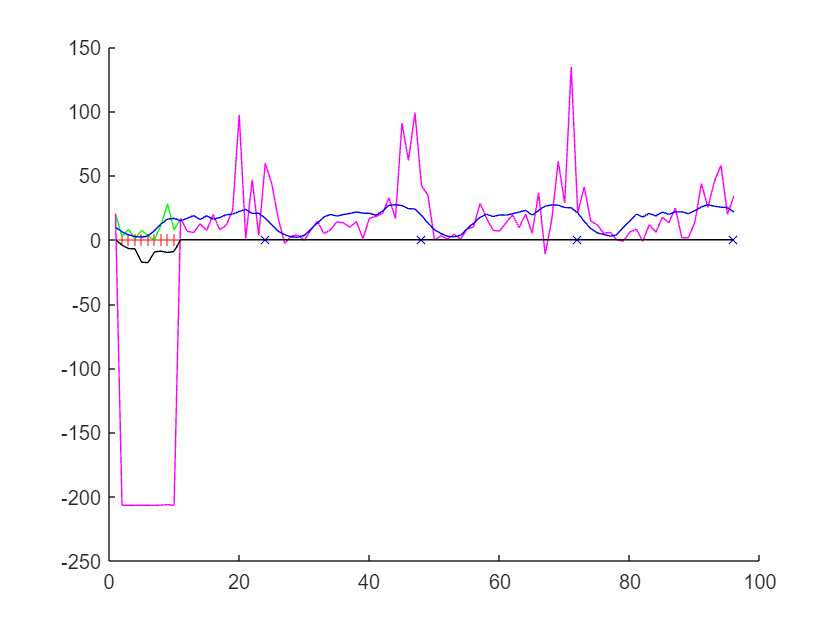

s= t2m(S,4);
l= t2m(L,4);
figure;
scatter(t(mod(1:96,24)==0),0,'bx')
hold on;

scatter(t(m(28,1:96)==1),0,'r+')
hold on
plot(y(28,1:96),'g')
plot(z(28,1:96),'m')
plot(l(28,1:96),'blue')
plot(s(28,1:96),'k')